clc;clear;
tic

% rng('default')


N = 2;
% Assume the number of sensors is N
N_i = [1,1];
% Assume the dimension of each sensors is N_i

M = 1;
% Suppose we choose M sensors in each step

T = 12;
% Assume the total time is T

ki_i = 0;

alpha = 0.99;
epsilon = 0.99;

% Generate the mathix batch by batch. I use eval function here before I
% find a better way to solve this problem.
% eval function has two obvious disadvantage:
% 1. it is very ugly and hard to read
% 2. opration times of eval function is very slow

states_number = T;
% State number
action_number = nchoosek(N,M);
% Action numbet
Q_table = zeros(action_number, states_number);



test_round = 1;
% test rounds

test_number = 1;
% test number. As there is some problems with dqn, I only design 5
% experiments here

Reward_all = zeros(test_number, test_round);
% How to evaluate the strategies? I use Reward_all.
% Each line stardards an experments and it can be updated with time.


%%%%%%%%%% generate corr_comb_num
corr_comb_num = zeros(nchoosek(N,M),M+1);
for i = 1:nchoosek(N,M)
    corr_comb_num(i,1) = i;
end
while ~isempty(find(corr_comb_num == 0))
    tmp = randperm(N);
    p = tmp(1:M);
    p = sort(p);
    out = comb2num(p,N,M);
    corr_comb_num(out,2:M+1) = p;
end
corr_comb_num;
% Some very strange methods are used to obtain the one-to-one correspondence between
% the serial number of combination number and combination, which is stored
% in corr_comb_num
%%%%%%%%%% end generate corr_comb_num



states_number = T;
% State number
action_number = nchoosek(N,M);
% Action numbet
Q_table = zeros(action_number, states_number);



%%%%%%%%%% start generate A_i, Q_i, C_i and R_i
% These four do not change with times
for i = 1:N
    eval(["A_" + num2str(i) + " = eye(N_i(i), N_i(i)) * (0.9);"]);
end
% Fixing A_i matrix
% Here A_i doesn't change when t changes. Actually it changes easily.

for i = 1:N
    eval(["Q_" + num2str(i) + " = eye(N_i(i))/10000;"]);
end
% Fixing error matrix Q_i

for i = 1:N
    eval(["C_" + num2str(i) + " = eye(N_i(i), N_i(i)) * (1 );"]);
end
% Fixing C_i matrix

for i = 1:N
    eval(["R_" + num2str(i) + " = eye(N_i(i))/10000;"]);
end
% Fixing error matrix R_i
%%%%%%%%%% end generate A_i, Q_i, C_i and R_i

P_record = zeros(1,6);


for test_times = 1:test_round
    % generate data again
    % rng(test_times * 10)
    % randomly choose seeds

    %%%%%%%%%% start generate error matrix, X_i and Y_i
    % These change with times
    for i = 1:N
        eval(["X_" + num2str(i) + " = zeros(N_i(i), T);"]);
    end
    for i = 1:N
        eval(["X_" + num2str(i) + "(:, 1) = ones(size(X_" + num2str(i) + "(:, 1)));"]);
    end
    % Initialize X_i matrix

    for i = 1:N
        for t = 1:T
            eval(["omega_" + num2str(i) + "_" + num2str(t) + " = zeros(N_i(i), N_i(i));"]);
            for k = 1:N_i(i)
                eval(["omega_" + num2str(i) + "_" + num2str(t) + "(k,k) = mvnrnd(0, Q_" + num2str(i) + "(N_i(i),N_i(i)));"]);
            end
        end
    end
    % Generate omega_i_t according to Q_i

    for i = 1:N
        eval(["Y_" + num2str(i) + " = ones(N_i(i), T);"]);
    end
    %     for i = 1:N
    %         eval(["Y_" + num2str(i) + "(:, i) = ones(size(Y_" + num2str(i) + "(:, 1))) *  (1);"]);
    %     end
    % Initialize Y_i matrix

    for i = 1:N
        for t = 1:T
            eval(["nu_" + num2str(i) + "_" + num2str(t) + " = zeros(N_i(i), N_i(i));"]);
            for k = 1:N_i(i)
                eval(["nu_" + num2str(i) + "_" + num2str(t) + "(k,k) = mvnrnd(0, R_" + num2str(i) + "(N_i(i),N_i(i)));"]);
            end
        end
    end
    % Generate nu_i_t according to R_i



    reward = 0;

    for i = 1:N
        eval(["P_" + num2str(i) + "_estimate = zeros(N_i(i),N_i(i));"]);
        % Initialize P_i_estimate matrix

        eval(["X_" + num2str(i) + "_estimate = zeros(1,1);"]);
        eval(["Y_" + num2str(i) + "_estimate = zeros(1,1);"]);
        % generate X_i_estimate and Y_i_estimate
    end

    %%%%%%%%%% Strategy1: total random
    reward = 0;

    for i = 1:N
        eval(["X_" + num2str(i) + "_estimated = zeros(1,T-1);"]);
        eval(["P_" + num2str(i) + "_estimated = zeros(1,T-1);"]);
    end


    for t = 1:T-1

        for i = 1:N
            for n = 1:N_i(i)
                eval(["X_" + num2str(i) + "(n, t+1) = A_" + num2str(i) + "(n,:)* X_" + num2str(i) + "(:, t) + omega_" + num2str(i) + "_" + num2str(t) + "(n,n);"]);
            end
        end
        % Calculate X_i according to delay matrix

        for i = 1:N
            eval(["Y_" + num2str(i) + "(:, t+1) = C_" + num2str(i) + " * Y_" + num2str(i) + "(:, t) + nu_" + num2str(i) + "_" + num2str(t) + " * ones(N_i(i),1);"]);
        end
        % Calculate Y_i according to X_i


        % Then we calculate reward and update Q_table

        trust_score = zeros(1,N);

        for i = 1:N
            eval(["Y_thisstep(i) = Y_" + num2str(i) + "(:, t);"]);
        end

        for i = 1:1
            if mod(t,3) == 2
                trust_score(i) = 0;
            end
        end

        for i = 1:N

            % eval(["[P_" + num2str(i) + ",X_" + num2str(i) + "_estimate] = Kalman_filter3(P_" + num2str(i) + "_estimate ,N_i(i) ,X_" + num2str(i) + "_estimate ,Y_" + num2str(i) + "(:, t), A_" + num2str(i) + ", C_" + num2str(i) + ", Q_" + num2str(i) + ", R_" + num2str(i) + ");"]);

            if trust_score(i) == 0
                eval(["P_" + num2str(i) + " = A_" + num2str(i) + " * P_" + num2str(i) + "_estimate * A_" + num2str(i) + "'+ Q_" + num2str(i) + ";"]);
                eval(["P_" + num2str(i) + "_estimate = P_" + num2str(i) + ";"]);
                eval(["X_" + num2str(i) + "_estimate = X_" + num2str(i) + "_estimated(1,t-1);"]);
            else
                eval(["x_" + num2str(i) + "_predicted = A_" + num2str(i) + " * X_" + num2str(i) + "_estimate;"]);
                eval(["P_" + num2str(i) + "_predicted = A_" + num2str(i) + " * P_" + num2str(i) + "_estimate * A_" + num2str(i) + "' + Q_" + num2str(i) + ";"]);
                % update
                eval(["K_new = (P_" + num2str(i) + "_predicted * C_" + num2str(i) + "') / (C_" + num2str(i) + " * P_" + num2str(i) + "_predicted * C_" + num2str(i) + "' + R_" + num2str(i) + ");"]);
                eval(["X_" + num2str(i) + "_estimate = x_" + num2str(i) + "_predicted + K_new * (Y_" + num2str(i) + "(:, t) - C_" + num2str(i) + " * x_" + num2str(i) + "_predicted);"]);
                eval(["P_" + num2str(i) + "_estimate = (eye(N_i(i), N_i(i)) - K_new * C_" + num2str(i) + ") * P_" + num2str(i) + "_predicted;"]);
                % estimate
            end


            eval(["X_" + num2str(i) + "_estimated(1,t) = X_" + num2str(i) + "_estimate;"]);
            eval(["P_" + num2str(i) + "_estimated(1,t) = P_" + num2str(i) + "_estimate;"]);



            % Update P_old_i
        end


        % Update P_i according to action



        for i = 1:N
            eval(["reward = reward + (X_" + num2str(i) + "_estimate - X_" + num2str(i) + "(:,t+1))^2;"]);
        end
        % Calculate reward

    end
    Reward_all(1,test_times) =  reward;
    P_record(1) = P_record(1) + P_1_estimate ;
    %%%%%%%%%% end Strategy1
end

Y_1

Y_1 =     1.0000    1.0012    1.0069    1.0110    1.0012    1.0088    1.0022    0.9962    0.9979    0.9949    0.9935    0.9995


Y_2

Y_2 =     1.0000    0.9980    1.0013    0.9989    1.0012    1.0056    0.9994    1.0022    1.0082    1.0091    1.0264    1.0203



X_1

X_1 =     1.0000    0.9059    0.8147    0.7130    0.6319    0.5748    0.5168    0.4539    0.4023    0.3645    0.3181    0.2961


X_2

X_2 =     1.0000    0.9181    0.8155    0.7359    0.6471    0.5752    0.5117    0.4646    0.4275    0.3878    0.3453    0.3189



X_1_estimated

X_1_estimated =     0.5000    0.5000    0.8294    0.9074    0.9074    0.9489    0.9443    0.9443    0.9518    0.9408    0.9408


X_2_estimated

X_2_estimated =     0.5000    0.7702    0.8767    0.9144    0.9294    0.9375    0.9368    0.9381    0.9422    0.9443    0.9553



P_1_estimated

P_1_estimated = 1.0e-03 *

    0.0500    0.1405    0.0681    0.0608    0.1493    0.0688    0.0609    0.1493    0.0688    0.0609    0.1493


P_2_estimated

P_2_estimated = 1.0e-04 *

    0.5000    0.5842    0.5957    0.5972    0.5974    0.5974    0.5974    0.5974    0.5974    0.5974    0.5974



figure
err1 = (X_1(2:end) - X_1_estimated).^2

err1 =     0.1648    0.0990    0.0136    0.0759    0.1106    0.1867    0.2404    0.2938    0.3449    0.3877    0.4157


plot(err1,"r")
hold on
err2 = (X_2(2:end) - X_2_estimated).^2

err2 =     0.1748    0.0021    0.0198    0.0714    0.1255    0.1813    0.2230    0.2607    0.3074    0.3588    0.4050


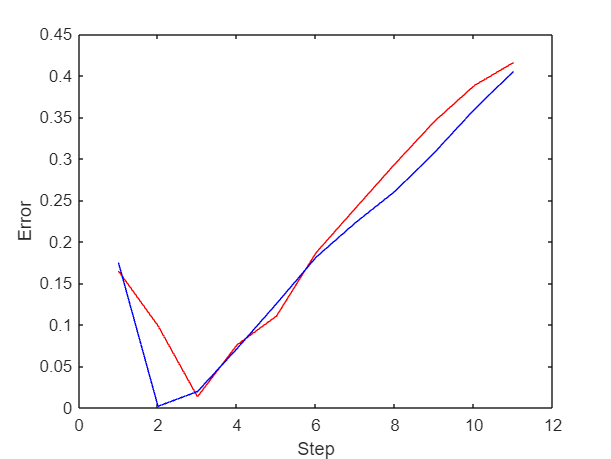

plot(err2,'b')
hold off
ylabel("Error")
xlabel("Step")

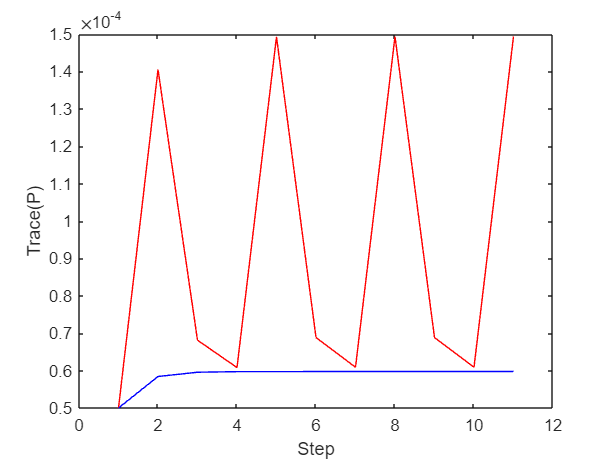


plot(P_1_estimated,"r")
hold on
plot(P_2_estimated,'b')
hold off
ylabel("Trace(P)")
xlabel("Step")